clc; clear; close all;
data = readtable('Five_times_Kinematics_HT_Query_MATLAB.xlsx');


fprintf('Dimensiones del dataset: %d filas x %d columnas\n', size(data,1), size(data,2));

Dimensiones del dataset: 50 filas x 87 columnas


disp('Variables del dataset:');

Variables del dataset:


disp(data.Properties.VariableNames);

    {'reclutado'}    {'GroupName'}    {'x1_AAFEM'}    {'x2_AAFEM'}    {'x3_AAFEM'}    {'x4_AAFEM'}    {'x5_AAFEM'}    {'x1_AAIEM'}    {'x2_AAIEM'}    {'x3_AAIEM'}    {'x4_AAIEM'}    {'x5_AAIEM'}    {'x1_AKFEM'}    {'x2_AKFEM'}    {'x3_AKFEM'}    {'x4_AKFEM'}    {'x5_AKFEM'}    {'x1_AKAAM'}    {'x2_AKAAM'}    {'x3_AKAAM'}    {'x4_AKAAM'}    {'x5_AKAAM'}    {'x1_AKIEM'}    {'x2_AKIEM'}    {'x3_AKIEM'}    {'x4_AKIEM'}    {'x5_AKIEM'}    {'x1_AHPFEM'}    {'x2_AHPFEM'}    {'x3_AHPFEM'}    {'x4_AHPFEM'}    {'x5_AHPFEM'}    {'x1_AHPAAM'}    {'x2_AHPAAM'}    {'x3_AHPAAM'}    {'x4_AHPAAM'}    {'x5_AHPAAM'}    {'x1_AHPIEM'}    {'x2_AHPIEM'}    {'x3_AHPIEM'}    {'x4_AHPIEM'}    {'x5_AHPIEM'}    {'x1_APTILTM'}    {'x2_APTILTM'}    {'x3_APTILTM'}    {'x4_APTILTM'}    {'x5_APTILTM'}    {'x1_APOBLIM'}    {'x2_APOBLIM'}    {'x3_APOBLIM'}    {'x4_APOBLIM'}    {'x5_APOBLIM'}    {'x1_APROTM'}    {'x2_APROTM'}    {'x3_APROTM'}    {'x4_APROTM'}    {'x5_APROTM'}    {'x1_ASPMLM'}    {'x2_ASPMLM'}    {'x3_ASP

isNum = varfun(@isnumeric, data, 'OutputFormat','uniform');
numericData = data(:, isNum);
X = table2array(numericData);
[n, p] = size(X);
fprintf('El dataset tiene %d muestras y %d dimensiones.\n', n, p);

El dataset tiene 50 muestras y 87 dimensiones.


Utilizamos QQ-plots para evaluar la normalidad de cada dimensión. 

fprintf('Evaluación de normalidad, QQ-plot CON outliers:\n');

Evaluación de normalidad, QQ-plot CON outliers:


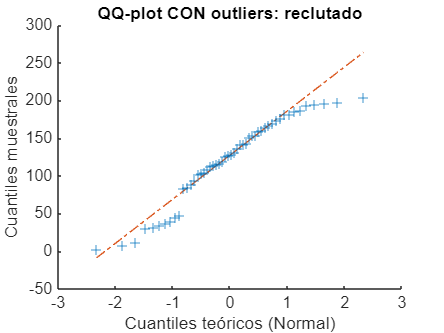

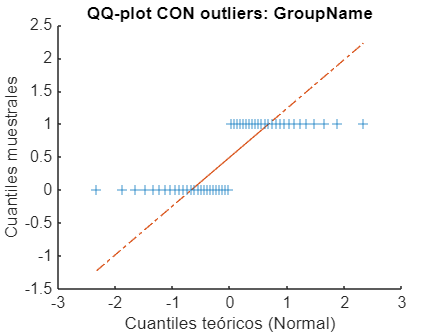

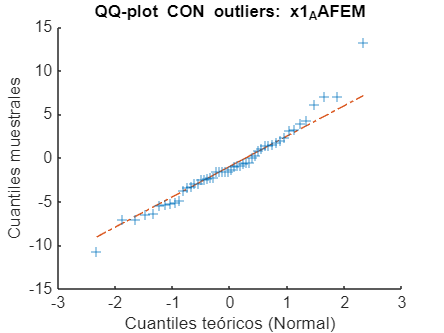

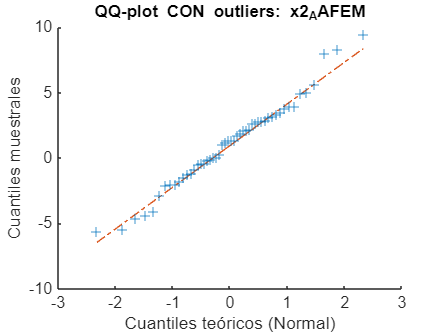

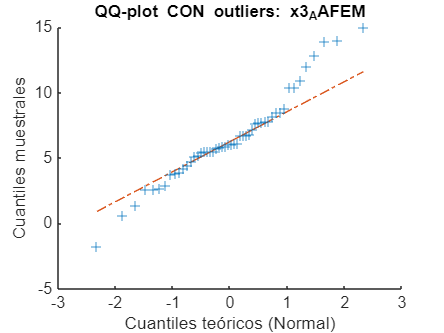

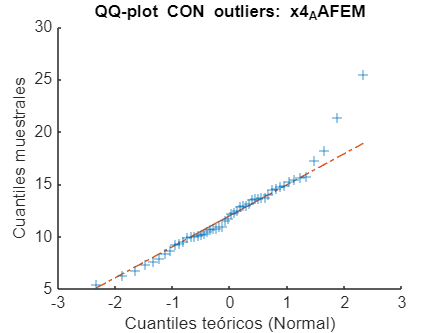

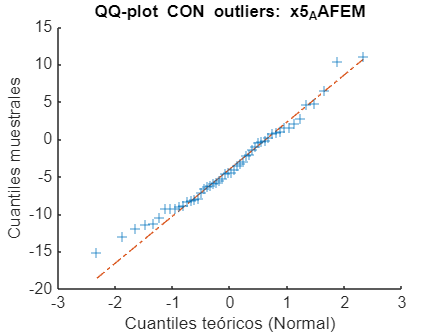

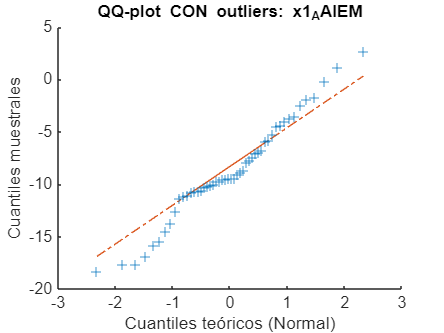

for j = 1:p
    colData = X(:, j);
    varName = numericData.Properties.VariableNames{j};
    
    % QQ-plot con outliers
    figure;
    qqplot(colData);
    title(['QQ-plot CON outliers: ', varName]);
    xlabel('Cuantiles teóricos (Normal)');
    ylabel('Cuantiles muestrales');
end

Una vez tenemos los QQ-plots analizamos si existen outliers:

% Estructura para guardar los outliers con nombres de variables 
outlierStruct = struct;

% Bucle por cada variable
for j = 1:p
    colData = X(:, j);
    varName = numericData.Properties.VariableNames{j};

    % Ordenar datos y calcular cuantiles teóricos normales
    sortedData = sort(colData);
    nObs = length(colData);
    prob = ((1:nObs)' - 0.5) / nObs;
    theorQ = norminv(prob, mean(colData), std(colData));

    % Residuales = distancia vertical del QQ-plot
    residuals = abs(sortedData - theorQ);

    % Umbral de outliers usando IQR (con coeficiente 2)
    Q1 = quantile(residuals, 0.25);
    Q3 = quantile(residuals, 0.75);
    IQR = Q3 - Q1;
    threshold = Q3 + 2 * IQR;

    % Índices de outliers con respecto al orden original
    [~, sortedIdx] = sort(colData);
    outlierLocalIdx = sortedIdx(residuals > threshold);
    outlierValues = colData(outlierLocalIdx);

    % Mostrar resultados
    fprintf('\nVariable "%s": %d outliers detectados.\n', varName, length(outlierLocalIdx));
    if ~isempty(outlierLocalIdx)
        fprintf('  IDs de outliers: %s\n', mat2str(outlierLocalIdx'));
    end

    % Guardar en la estructura
    outlierStruct.(varName).nOutliers = length(outlierLocalIdx);
    outlierStruct.(varName).ID = outlierLocalIdx;
    outlierStruct.(varName).valores = outlierValues;
end


Variable "reclutado": 5 outliers detectados.


  IDs de outliers: [4 31 30 25 26]



Variable "GroupName": 0 outliers detectados.

Variable "x1_AAFEM": 2 outliers detectados.


  IDs de outliers: [5 27]



Variable "x2_AAFEM": 1 outliers detectados.


  IDs de outliers: 47



Variable "x3_AAFEM": 1 outliers detectados.


  IDs de outliers: 27



Variable "x4_AAFEM": 3 outliers detectados.


  IDs de outliers: [29 1 27]



Variable "x5_AAFEM": 2 outliers detectados.


  IDs de outliers: [25 32]



Variable "x1_AAIEM": 0 outliers detectados.

Variable "x2_AAIEM": 0 outliers detectados.

Variable "x3_AAIEM": 1 outliers detectados.


  IDs de outliers: 40



Variable "x4_AAIEM": 0 outliers detectados.

Variable "x5_AAIEM": 2 outliers detectados.


  IDs de outliers: [16 33]



Variable "x1_AKFEM": 2 outliers detectados.


  IDs de outliers: [47 8]



Variable "x2_AKFEM": 2 outliers detectados.


  IDs de outliers: [45 14]



Variable "x3_AKFEM": 3 outliers detectados.


  IDs de outliers: [45 27 8]



Variable "x4_AKFEM": 4 outliers detectados.


  IDs de outliers: [4 45 8 47]



Variable "x5_AKFEM": 2 outliers detectados.


  IDs de outliers: [16 47]



Variable "x1_AKAAM": 1 outliers detectados.


  IDs de outliers: 41



Variable "x2_AKAAM": 3 outliers detectados.


  IDs de outliers: [8 24 41]



Variable "x3_AKAAM": 4 outliers detectados.


  IDs de outliers: [8 25 19 41]



Variable "x4_AKAAM": 1 outliers detectados.


  IDs de outliers: 41



Variable "x5_AKAAM": 2 outliers detectados.


  IDs de outliers: [31 36]



Variable "x1_AKIEM": 2 outliers detectados.


  IDs de outliers: [15 4]



Variable "x2_AKIEM": 2 outliers detectados.


  IDs de outliers: [46 4]



Variable "x3_AKIEM": 2 outliers detectados.


  IDs de outliers: [46 4]



Variable "x4_AKIEM": 2 outliers detectados.


  IDs de outliers: [46 7]



Variable "x5_AKIEM": 1 outliers detectados.


  IDs de outliers: 46



Variable "x1_AHPFEM": 5 outliers detectados.


  IDs de outliers: [37 45 12 40 8]



Variable "x2_AHPFEM": 1 outliers detectados.


  IDs de outliers: 5



Variable "x3_AHPFEM": 2 outliers detectados.


  IDs de outliers: [27 29]



Variable "x4_AHPFEM": 1 outliers detectados.


  IDs de outliers: 5



Variable "x5_AHPFEM": 1 outliers detectados.


  IDs de outliers: 45



Variable "x1_AHPAAM": 1 outliers detectados.


  IDs de outliers: 38



Variable "x2_AHPAAM": 1 outliers detectados.


  IDs de outliers: 41



Variable "x3_AHPAAM": 2 outliers detectados.


  IDs de outliers: [41 38]



Variable "x4_AHPAAM": 1 outliers detectados.


  IDs de outliers: 41



Variable "x5_AHPAAM": 1 outliers detectados.


  IDs de outliers: 25



Variable "x1_AHPIEM": 3 outliers detectados.


  IDs de outliers: [5 8 42]



Variable "x2_AHPIEM": 0 outliers detectados.

Variable "x3_AHPIEM": 3 outliers detectados.


  IDs de outliers: [50 29 42]



Variable "x4_AHPIEM": 3 outliers detectados.


  IDs de outliers: [27 42 35]



Variable "x5_AHPIEM": 1 outliers detectados.


  IDs de outliers: 32



Variable "x1_APTILTM": 2 outliers detectados.


  IDs de outliers: [5 47]



Variable "x2_APTILTM": 1 outliers detectados.


  IDs de outliers: 37



Variable "x3_APTILTM": 1 outliers detectados.


  IDs de outliers: 5



Variable "x4_APTILTM": 1 outliers detectados.


  IDs de outliers: 5



Variable "x5_APTILTM": 1 outliers detectados.


  IDs de outliers: 37



Variable "x1_APOBLIM": 3 outliers detectados.


  IDs de outliers: [44 25 13]



Variable "x2_APOBLIM": 4 outliers detectados.


  IDs de outliers: [47 22 11 38]



Variable "x3_APOBLIM": 2 outliers detectados.


  IDs de outliers: [44 38]



Variable "x4_APOBLIM": 2 outliers detectados.


  IDs de outliers: [7 13]



Variable "x5_APOBLIM": 2 outliers detectados.


  IDs de outliers: [7 34]



Variable "x1_APROTM": 4 outliers detectados.


  IDs de outliers: [43 35 27 1]



Variable "x2_APROTM": 1 outliers detectados.


  IDs de outliers: 1



Variable "x3_APROTM": 4 outliers detectados.


  IDs de outliers: [43 50 31 1]



Variable "x4_APROTM": 3 outliers detectados.


  IDs de outliers: [35 9 1]



Variable "x5_APROTM": 2 outliers detectados.


  IDs de outliers: [43 35]



Variable "x1_ASPMLM": 2 outliers detectados.


  IDs de outliers: [36 29]



Variable "x2_ASPMLM": 2 outliers detectados.


  IDs de outliers: [32 36]



Variable "x3_ASPMLM": 1 outliers detectados.


  IDs de outliers: 42



Variable "x4_ASPMLM": 3 outliers detectados.


  IDs de outliers: [27 21 8]



Variable "x5_ASPMLM": 0 outliers detectados.

Variable "x1_ASPIEM": 4 outliers detectados.


  IDs de outliers: [8 6 7 1]



Variable "x2_ASPIEM": 2 outliers detectados.


  IDs de outliers: [7 1]



Variable "x3_ASPIEM": 2 outliers detectados.


  IDs de outliers: [8 1]



Variable "x4_ASPIEM": 2 outliers detectados.


  IDs de outliers: [21 1]



Variable "x5_ASPIEM": 2 outliers detectados.


  IDs de outliers: [12 1]



Variable "x1_ASHTILTOFFM": 2 outliers detectados.


  IDs de outliers: [38 21]



Variable "x2_ASHTILTOFFM": 1 outliers detectados.


  IDs de outliers: 21



Variable "x3_ASHTILTOFFM": 2 outliers detectados.


  IDs de outliers: [39 21]



Variable "x4_ASHTILTOFFM": 1 outliers detectados.


  IDs de outliers: 21



Variable "x5_ASHTILTOFFM": 3 outliers detectados.


  IDs de outliers: [39 1 21]



Variable "x1_ASHOBLIOFFM": 3 outliers detectados.


  IDs de outliers: [1 10 47]



Variable "x2_ASHOBLIOFFM": 2 outliers detectados.


  IDs de outliers: [41 50]



Variable "x3_ASHOBLIOFFM": 1 outliers detectados.


  IDs de outliers: 41



Variable "x4_ASHOBLIOFFM": 2 outliers detectados.


  IDs de outliers: [41 35]



Variable "x5_ASHOBLIOFFM": 1 outliers detectados.


  IDs de outliers: 47



Variable "x1_ASHROTOFFM": 1 outliers detectados.


  IDs de outliers: 29



Variable "x2_ASHROTOFFM": 2 outliers detectados.


  IDs de outliers: [4 41]



Variable "x3_ASHROTOFFM": 1 outliers detectados.


  IDs de outliers: 41



Variable "x4_ASHROTOFFM": 3 outliers detectados.


  IDs de outliers: [34 35 41]



Variable "x5_ASHROTOFFM": 2 outliers detectados.


  IDs de outliers: [21 41]



Variable "x1_ASPFEM": 1 outliers detectados.


  IDs de outliers: 6



Variable "x2_ASPFEM": 3 outliers detectados.


  IDs de outliers: [45 10 43]



Variable "x3_ASPFEM": 2 outliers detectados.


  IDs de outliers: [45 43]



Variable "x4_ASPFEM": 2 outliers detectados.


  IDs de outliers: [45 8]



Variable "x5_ASPFEM": 2 outliers detectados.


  IDs de outliers: [45 8]


allOutlierIDs = [];

% Recorrer todas las variables en outlierStruct
varNames = fieldnames(outlierStruct);
for i = 1:numel(varNames)
    allOutlierIDs = [allOutlierIDs; outlierStruct.(varNames{i}).ID];
end

% Quitar duplicados y ordenar
allOutlierIDs = unique(allOutlierIDs);
disp('Todas las IDs de muestras con al menos un outlier:');

Todas las IDs de muestras con al menos un outlier:


disp(allOutlierIDs');

     1     4     5     6     7     8     9    10    11    12    13    14    15    16    19    21    22    24    25    26    27    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    50



% Total de filas (observaciones)
allIDs = (1:n)';  % n = número total de muestras

% Obtener todas las IDs únicas de outliers
outlierIDs = [];

varNames = fieldnames(outlierStruct);
for i = 1:numel(varNames)
    outlierIDs = [outlierIDs; outlierStruct.(varNames{i}).ID];
end

% Eliminar duplicados
outlierIDs = unique(outlierIDs);

% Obtener las filas que no son outliers
nonOutlierIDs = setdiff(allIDs, outlierIDs);

% Mostrar
fprintf('Número de muestras sin outliers: %d\n', numel(nonOutlierIDs));

Número de muestras sin outliers: 9


disp('IDs de filas sin outliers:');

IDs de filas sin outliers:


disp(nonOutlierIDs');

     2     3    17    18    20    23    28    48    49



Hemos detectado, 4 outliers significativos que son el **1, 21,27 y el 41**

Procederemos a eliminarlos y realizaremos otra vez el análisis.